% Clear workspace and command window
clear;
clc;

% Read data from the Excel file
data = readtable('COMBINATIONJANMAY2024.xlsx');

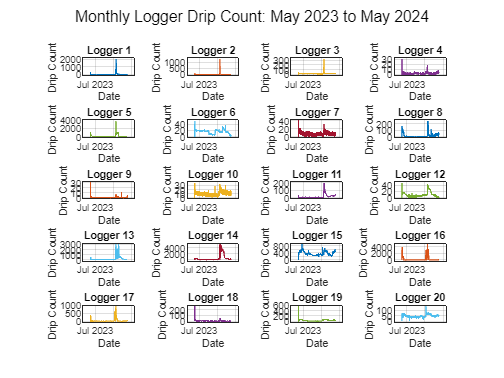


% Extract dates, rainfall, and drip count data
dates = data{:, 1}; %time is in column 1
drip_count = data{:, 2:21}; % Drip count is in columns 2 to 21

% Create a figure with 20 subplots
figure; clf
hold on;

% Define a set of colors (20 unique colors)
colors = lines(20);  % Use MATLAB's 'lines' colormap, to generate different colors

% Plot drip count dataset 
for i = 1:20
    subplot(5,4,i);
    plot(dates, drip_count(:,i),'Color', colors(i, :));
    ylabel('Drip Count');
    xlabel('Date');
    % Rotate x-axis labels for better readability
    xtickangle(0);
    % Adjust plot
    grid on;
    axis padded
    % Adjust subplot title
    title(['Logger ' num2str(i)]);
sgtitle('Monthly Logger Drip Count: May 2023 to May 2024')
hold off;
end